# Comparison of two conditions

We have already seen how to create a model with rFASTCORMICS. We will create two generic breast cancer models based on 25 randomly selected cancer and healthy samples from the TCGA . We will also create 25 healthy models as well as 25 cancer models.

We have provided the fpkm data in breast.mat

Load the data, discretize the data, and create one generic healthy and one cancer model.

addpath(genpath(pwd))

load breast.mat

colnames_cancer = strcat('cancer_',BRCA_cancer.Properties.VariableNames);
colnames_healthy = strcat('healthy_',BRCA_healthy.Properties.VariableNames);

## Create context-specific BRCA models

Use FASTCORMICS to create model(s) for BRCA_cancer and for BRCA_healthy. 

## Transform the table into an array

BRCA_cancer = table2array(BRCA_cancer);
BRCA_healthy = table2array(BRCA_healthy);

### PCA on FPKM data

You can use mapcaplot to visualize the data, however you will have to log2 transform it first.

Have a look at the documentation of *mapcaplot* to find out how it works.

signal = log2([BRCA_cancer, BRCA_healthy]);
signal(isinf(signal)) = -10000;

mapcaplot(signal',[colnames_cancer, colnames_healthy])


This code will give you the same result:

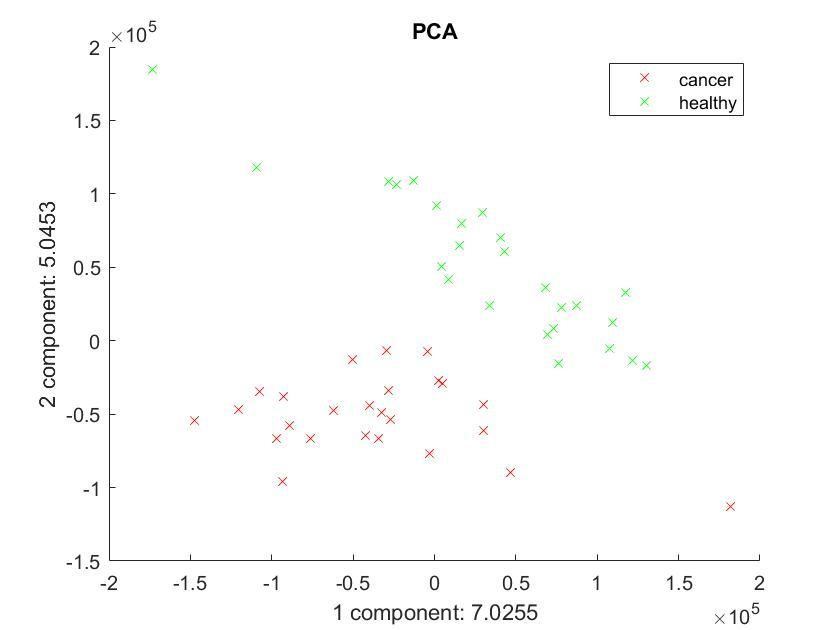

[~,score,~,~,explained,~] = pca([signal]');
figure
hold on
plot(score(1:25,1),score(1:25,2),'rx')
plot(score(26:50,1),score(26:50,2),'gx')
title('PCA')
xlabel([num2str(1), ' component: ', num2str(explained(1))])
ylabel([num2str(2), ' component: ', num2str(explained(2))])
legend({'cancer','healthy'},'location','best')

## Discretize the data

Now discretize the data using the discretize_FPKM as in the previous exercise.

Call the variables 

- BRCA_cancer_discr

- BRCA_healthy_discr

BRCA_cancer_discr = discretize_FPKM(BRCA_cancer,colnames_cancer);
BRCA_healthy_discr = discretize_FPKM(BRCA_healthy, colnames_healthy);

**Number of expressed/unexpressed genes**

You can create a figure to visualize how many genes are expressed, inexpressed or unknonw.

figure
subplot(2,1,1)
bar([mean(sum(BRCA_cancer_discr==-1));mean(sum(BRCA_cancer_discr==0));mean(sum(BRCA_cancer_discr==1))]/size(BRCA_cancer_discr,1))
hold onerrorbar([mean(sum(BRCA_cancer_discr==-1));mean(sum(BRCA_cancer_discr==0));mean(sum(BRCA_cancer_discr==1))]/size(BRCA_cancer_discr,1),...
    [std(sum(BRCA_cancer_discr==-1));std(sum(BRCA_cancer_discr==0));std(sum(BRCA_cancer_discr==1))]/size(BRCA_cancer_discr,1),'.')
set(gca, 'XTickLabel', {'-1, unexpressed','0, unknown','1, expressed'})
ylabel('Ratio')
title('Cancer genes')

subplot(2,1,2)
bar([mean(sum(BRCA_healthy_discr==-1));mean(sum(BRCA_healthy_discr==0));mean(sum(BRCA_healthy_discr==1))]/size(BRCA_healthy_discr,1))
hold on
errorbar([mean(sum(BRCA_healthy_discr==-1));mean(sum(BRCA_healthy_discr==0));mean(sum(BRCA_healthy_discr==1))]/size(BRCA_healthy_discr,1),...
    [std(sum(BRCA_healthy_discr==-1));std(sum(BRCA_healthy_discr==0));std(sum(BRCA_healthy_discr==1))]/size(BRCA_healthy_discr,1),'.')

set(gca, 'XTickLabel', {'-1, unexpressed','0, unknown','1, expressed'})
ylabel('Ratio')
title('Healthy genes')

Invalid expression. When calling a function or indexing a variable, use parentheses. Otherwise, check for mismatched delimiters.

## FASTCORMICS

We wll now use FASTCORMICS to create 2 generic models, therefore we need to inititialize FASTCORMICS first.

**Initialize FASTCORMICS**

load dico %for mapping the SYMBOLS to the ENTREZ IDs
load optional_settings.mat %otional settings
load medium_example.mat %medium composition

load Recon204.mat % we will use Recon2 for this example
consistent_model = CmodelR204;

already_mapped_tag = 0;
consensus_proportion = 0.9; %only if a gene is expressed in 90% of the samples, the genes will be considered active
epsilon = 1e-4;

In the optional_settings, there are 2 reactions that are forced to be in the model. If you perform other experiments, you can add more if needed. These reaction will ALWAYS be included.

optional_settings.func

## Create generic cancer models

create one model for cancer and one model for healthy. Use all the 25 samples from 

- BRCA_cancer_discr: call it A_final_cancer

- BRCA_healthy_discr: call it A_final_healthy

[~, A_final_cancer] = fastcormics_RNAseq(consistent_model, BRCA_cancer_discr, rownames, dico,'biomass_reaction', already_mapped_tag, consensus_proportion, epsilon, optional_settings)
[~, A_final_healthy] = fastcormics_RNAseq(consistent_model, BRCA_healthy_discr, rownames, dico,'biomass_reaction', already_mapped_tag, consensus_proportion, epsilon, optional_settings)

Create models_keep_generic matrix based on an empty zero matrix (size: number of reactions in the consistent model x 2). Change reactions to 1, if it is present in the model.

Use both A_final_cancer and A_final_healthy to create it. Column 1 should be the cancer model and column 2 should be the healthy model.

models_keep_generic = zeros(numel(consistent_model.rxns),2);
models_keep_generic(A_final_cancer,1) = 1;
models_keep_generic(A_final_healthy,2) = 1;

You can check the sizes of the model by using

sum(models_keep_generic)

The healthy model is bigger than the cancer model.

Write a code to visualize the reaction presence

use imagesc on the models_keep_generic. In yellow you see those reactions that are active (1) in the context of interest.

figure
imagesc(models_keep_generic)
title('reaction presence')
ylabel('reactions')
colorbar
xticks(1:2)
xticklabels({'cancer','healthy'})

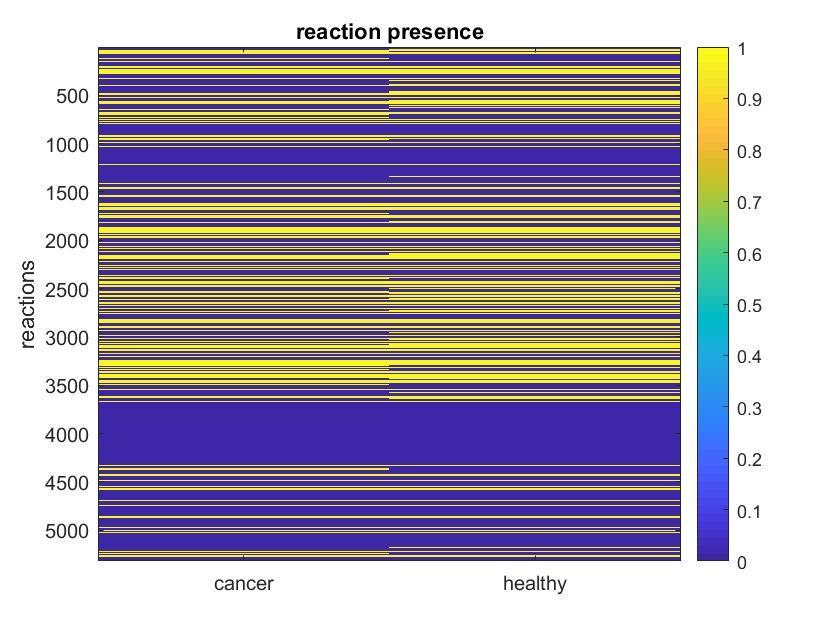

We will now represent the pathway presence rate of both generic models.

For this we will create a table that contains the number of reactions per pathways.

To start, we will create the table for the consistent model

Pathways = table(unique(consistent_model.subSystems));

Based on the previous exercice we will get the number of reactions per pathway:

[pathways, ~, ub] = unique(consistent_model.subSystems);
path_counts = histc(ub, 1:length(pathways));
T = table(pathways, path_counts);

Then we will add these number to the Pathways table.

[I, ia, ib] = intersect(Pathways.Var1, T.pathways);
Pathways.consistent(ia) = T.path_counts(ib) ;

Now do the same for the cancer and healthy model. You should receive a Table with 90 rows and 4 columns (Var1, consistent, cancer, healthy)

[pathways, ~, ub] = unique(consistent_model.subSystems(find(models_keep_generic(:,1))));
path_counts_cancer = histc(ub, 1:length(pathways));
T_cancer = table(pathways, path_counts_cancer);

[pathways, ~, ub] = unique(consistent_model.subSystems(find(models_keep_generic(:,2))));
path_counts_healthy = histc(ub, 1:length(pathways));
T_healthy = table(pathways, path_counts_healthy);


[I, ia, ib] = intersect(Pathways.Var1, T_cancer.pathways);
Pathways.Cancer(ia) = T_cancer.path_counts_cancer(ib) ;

[I, ia, ib] = intersect(Pathways.Var1, T_healthy.pathways);
Pathways.Healthy(ia) = T_healthy.path_counts_healthy(ib);

Pathways % to show the table

Now we can already do a **barplot for the number of reactions in each pathway**:

use bar to show the number of reactions per pathway. You can either plot both plots on top of each other or in separate figures.

figure
hold on
bar(Pathways.Healthy)
bar(Pathways.Cancer)
legend('Healthy','Cancer')
title('number of pathways')

We will now create the reaction presence plot. Therefore, we will divide the number of pathway in the cancer and the healthy model by the number of pathways in the consistent model. Do it for both the healthy and the cancer model.

Do another barplot. Try to sort it by the reaction presence of cancer.

figure
hold on
bar(Pathways.Cancer./Pathways.consistent)
bar(Pathways.Healthy./Pathways.consistent)

We can represent the same in a scatterplot: Healthy vs. Cancer. It will show what pathways are up or down-regulated in cancer and healthy.

You can either use plot(x,y) or scatter to create the plot

figure
plot(Pathways.Cancer./Pathways.consistent, Pathways.Healthy./Pathways.consistent,'x')
xlabel('Cancer')
ylabel('healthy')
title('Scatterplot')

## Gene deletion

Now perform gene deletion on both the cancer and the healthy model. 

You will perform 4 single gene deletions in total. In the first, you will optimize for the biomass called 'biomass_reaction' and in the second you will use the ATP demand reaction called 'DM_atp_c_' for both models.

Make sure to save the grRatio in either 4 different variables or in the same variables with different columns.

changeCobraSolver('ibm_cplex')
for i=1:size(models_keep_generic,2) %for each model
    
    %ATP
    ind = find(~cellfun(@isempty, regexp(consistent_model.rxns,optional_settings.func{1})));
    model_out = removeRxns(consistent_model,consistent_model.rxns(setdiff(1:numel(consistent_model.rxns),find(models_keep_generic(:,i))))); % create model based on active reactions
    model_out = changeObjective(model_out,consistent_model.rxns(ind)); % set objective function
    
    [grRatio, grRateKO, grRateWT, ~, ~, ~] = singleGeneDeletion_rFASTCORMICS(model_out,'FBA',[],0,1);
    
    grRatio_ATP_generic(:,i)=grRatio;
    
    
    %Biomass
    ind = find(~cellfun(@isempty, regexp(consistent_model.rxns,optional_settings.func{2})));
    model_out = removeRxns(consistent_model,consistent_model.rxns(setdiff(1:numel(consistent_model.rxns),find(models_keep_generic(:,i))))); % create model based on active reactions
    model_out = changeObjective(model_out,consistent_model.rxns(ind)); % set objective function
    
    [grRatio, grRateKO, grRateWT, ~, ~, ~] = singleGeneDeletion_rFASTCORMICS(model_out,'FBA',[],0,1);
    
    grRatio_biomass_generic(:,i)=grRatio;
    
    
end

**Visualize the growth ratio**

use plot(sort(grRatioX)) for all the 4 gene deletions:

Do not forget to add a legend.

The plot should look like this:

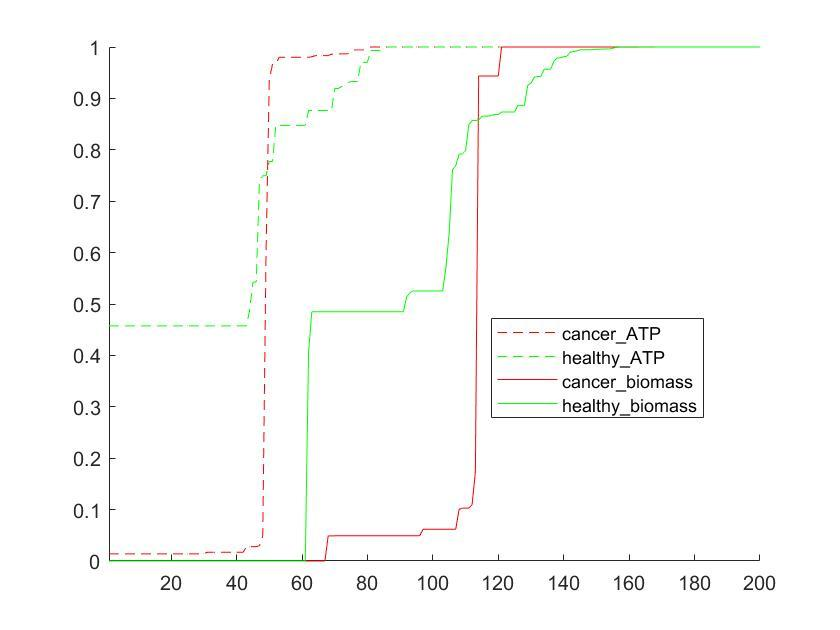

figure
hold on
plot(sort(grRatio_ATP_generic(:,1)),'--r')
plot(sort(grRatio_ATP_generic(:,2)),'--g')
plot(sort(grRatio_biomass_generic(:,1)),'r')
plot(sort(grRatio_biomass_generic(:,2)),'g')
xlim([1 200])
legend({'cancer_ATP','healthy_ATP','cancer_biomass','healthy_biomass'},'Interpreter','none','Location','best')

## Create single models

You can also use FASTCORMICS to create single models, for this you can write a for loop for each column in the discretized data.

However, due to time constraints in these practicals, only create a model for the first cancer and the first healthy sample and create the models_keep variable.

for i=1:25
    [~, A_final_cancer_single{i}] = fastcormics_RNAseq(consistent_model, BRCA_cancer_discr(:,i), rownames, dico, ...
         'biomass_reaction',already_mapped_tag, consensus_proportion, epsilon, optional_settings);
    [~, A_final_healthy_single{i}] = fastcormics_RNAseq(consistent_model, BRCA_healthy_discr(:,i), rownames, dico, ...
        'biomass_reaction',already_mapped_tag, consensus_proportion, epsilon, optional_settings);
end

create the models_keep_single variable for these samples:

models_keep_single = zeros(numel(consistent_model.rxns), 50)

for i=1:25
    models_keep_single(A_final_cancer_single{i},i) = 1
    models_keep_single(A_final_healthy_single{i},i+25) = 1
end


We have already provided the models_keep for all the 50 samples:

columns 1:25 correspond to the cancer samples and columns 26:50 correspond to the healthy samples.

load models_keep_single

## Visualization

Create boxplots based on the model sizes. You want to compare the distribution of the cancer and the healthy models. The model size can be obtained from the sum of models_keep_single

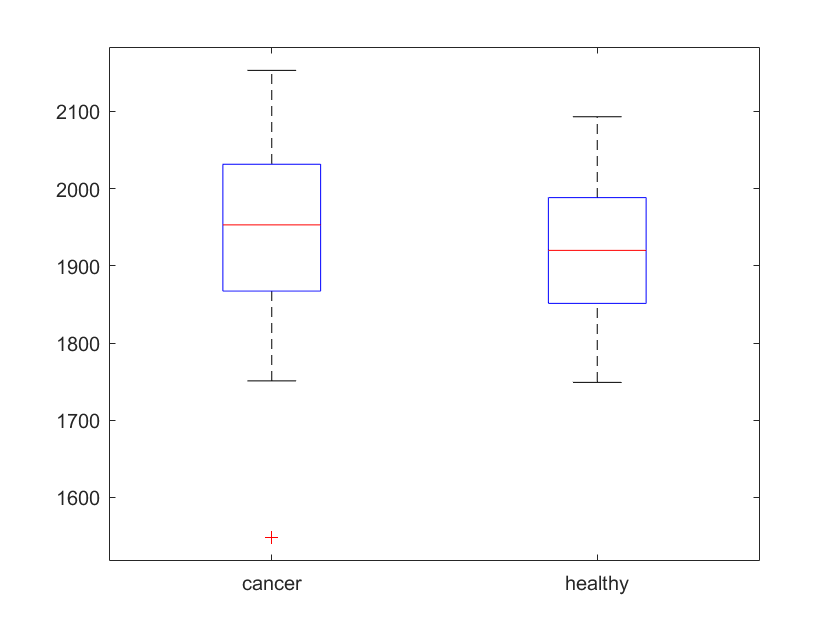

figure
boxplot([sum(models_keep_single(:,1:25)); sum(models_keep_single(:,26:50))]')
xticklabels({'cancer','healthy'})

**Model similarity**

We can use the Jaccard distance between the reaction presence in the models so see how similar models are.

To do so, we will create the distance matrix for each model:

Use the documenatation to read more on these functions.

J = squareform(pdist(models_keep_single','jaccard'));

We can easily represent this matrix, which compares each model with itself and the other models:

figure
imagesc(J);
title('Reaction presence in models: Jaccard index');
colorbar;
xticks(1:size(models_keep_single,2))
yticks(1:size(models_keep_single,2))
yticklabels([colnames_cancer,colnames_healthy])


This figure does not look very ordered. We can use clustergram to visualize the same data but in this case,  those models that are similar, will appear next to each other. It is a nice way to find clusters of models that are similar.

altcolor= [255 255 255;255 204 204; 255 153 153; 255 102 102; 255 51 51;...
    255 0 0; 204 0 0; 152 0 0; 102 0 0;  51 0 0; 0 0 0]/255; %some red color


cgo_J = clustergram(1-J,...
    'RowLabels', [colnames_cancer,colnames_healthy],...
    'ColumnLabels', [colnames_cancer,colnames_healthy],...
    'ColumnLabelsRotate',270, ...
    'Cluster', 'all', ...
    'symmetric','False',...
    'Colormap', altcolor)
addTitle(cgo_J, {'Clustergram for single models', 'Jaccard index on reaction presence in models'},'Interpreter','none')
h=plot(cgo_J);
set(h,'TickLabelInterpreter','none');